exctract data from file:

clear all
%%PARAMETERS%%
FREQ_BIT_START = 19000;  % 19 kHz
FREQ_BIT_1 = 18000;  % 18 kHz
FREQ_BIT_STOP = 18500;  % 19 kHz
tone_length=10e-3; %length in seconds
audioFile = "Test.m4a";
key='AWESOMEKEY';

% Read the audio file.
[x, Fs] = audioread(audioFile);
plot(x);
title('Audio signal in time domain')
xlabel('time (1/Fs)') 
ylabel('Magnitude') 
sound(x, Fs)

Now "x" contains all the sampled data present in the audio file. we can check the spectum of the signal with fft:

N = length(x); % Length of the audio signal
Y = fft(x);    % Compute the FFT

The prevous is the double side spectrum, we want to compute the single side spectrum:

P2 = abs(Y/N); 
magnitude = P2(1:floor(N/2+1));
magnitude(2:end-1) = 2*magnitude(2:end-1);

%Plot the FFT results
f = Fs*(0:(N/2))/N; % Frequency vector
figure;
plot(f, magnitude);
title('FFT of Audio Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
hold on; % To overlay the line on the existing plot


We can see that there is some content between the frequency 18kHz and 19kHz

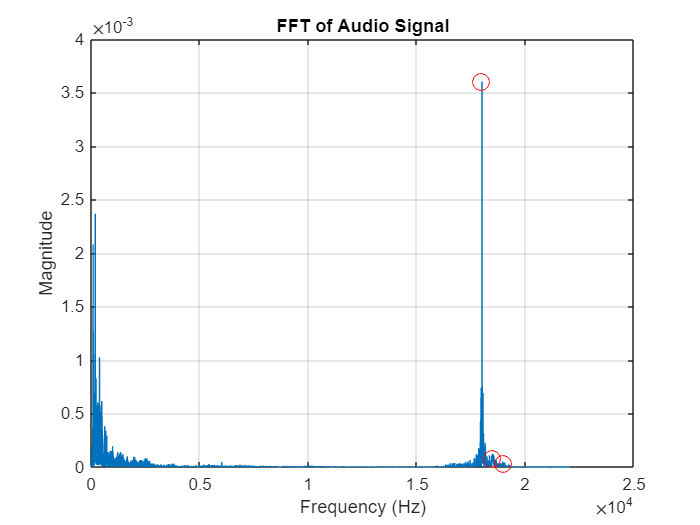


% Mark the point with a red circle
[~, index] = min(abs(f - FREQ_BIT_START));
hold on;
plot(f(index), magnitude(index), 'ro', 'MarkerSize', 10);
[~, index] = min(abs(f - 17999.6));
plot(f(index), magnitude(index), 'ro', 'MarkerSize', 10); 
[~, index] = min(abs(f - FREQ_BIT_STOP));
plot(f(index), magnitude(index), 'ro', 'MarkerSize', 10);
hold off; 

Now we can filter those frequencies and analyze the content

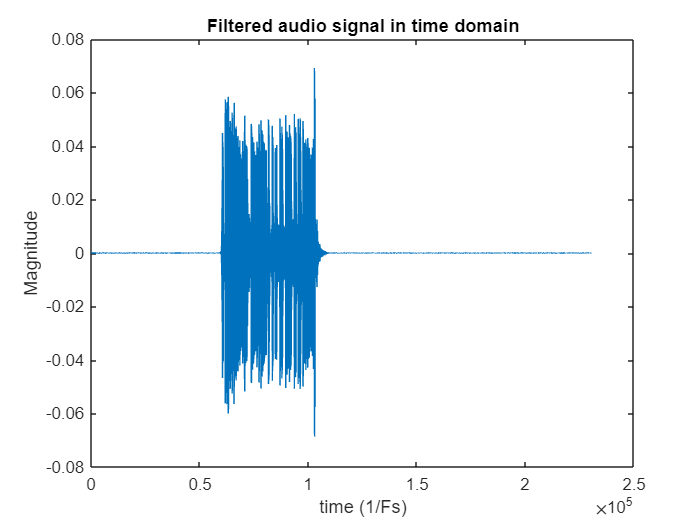

%filtering with band pass
x = bandpass(x,[0.8 0.9],'Steepness',0.85,'StopbandAttenuation',90);
N = length(x); 
plot(x);
title('Filtered audio signal in time domain')
xlabel('time (1/Fs)') 
ylabel('Magnitude') 

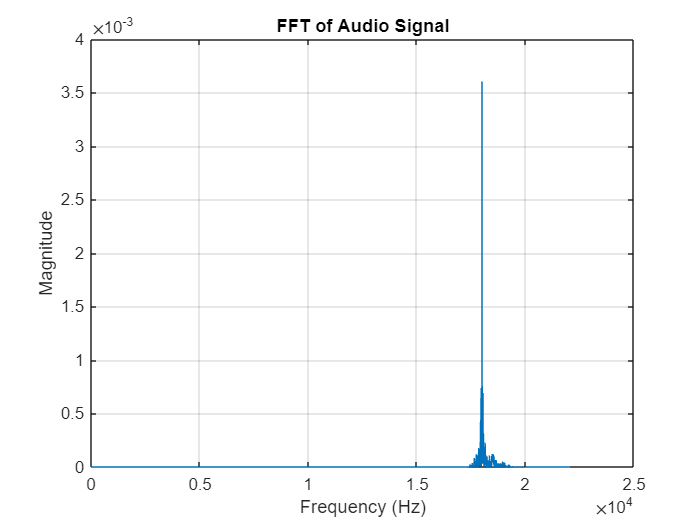

sound(x, Fs)
Y = fft(x);    
P2 = abs(Y/N); 
magnitude = P2(1:floor(N/2+1));
magnitude(2:end-1) = 2*magnitude(2:end-1);

%Plot the FFT results
f = Fs*(0:(N/2))/N; % Frequency vector
figure;
plot(f, magnitude);
title('FFT of Audio Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

let's compare the result using goertzel algorithm

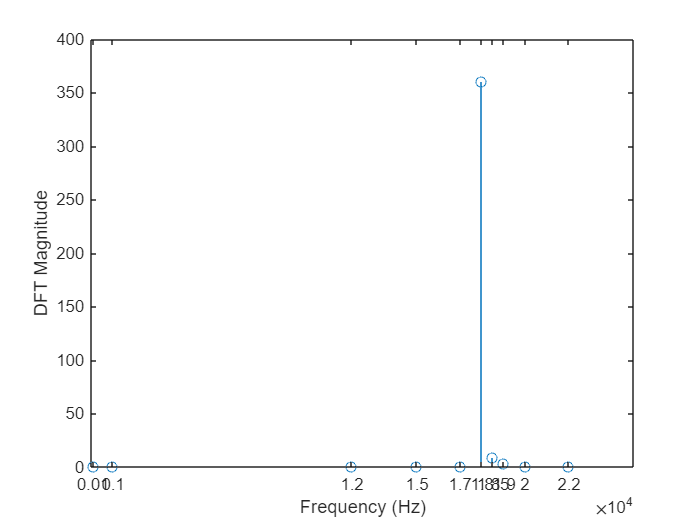

frequencies = [ 100, 1000, 12000, 15000, 17000, FREQ_BIT_1, FREQ_BIT_STOP, FREQ_BIT_START,20000, 22000];
freq_indices= round(frequencies/Fs*length(x))+1;
gdft= goertzel(x, freq_indices);
stem(frequencies,abs(gdft))
ax = gca;
ax.XTick = frequencies;
% xlim(ax,[100,22000])
xlabel('Frequency (Hz)')
ylabel('DFT Magnitude')

The goertzel algorithm is more efficient in calculating the dft at determined frequency. From this dft analysis we can extract the maximum values that will be used for calculating the  threshold:

thr_start = abs(gdft(8))

thr_start = 3.3997

thr_stop = abs(gdft(7))

thr_stop = 9.1462

thr_bit1 = abs(gdft(6))

thr_bit1 = 360.1869

The general idea is to divide the signal into intervals and then check the presence of one or the one frequency with goertzel algorithm, but before we need to find the starting point of the comunication, to do so we can use the correlation function to find the position of bit start, by generating a reference tone signal

%reference tone signal
bitstart_tone = sin(2 * pi * FREQ_BIT_START * (0:1/Fs:tone_length - 1/Fs));
[r, lags] = xcorr(x, bitstart_tone);
plot(lags,r)

we can find the maximum correlation that corresponds to the initial time of the message

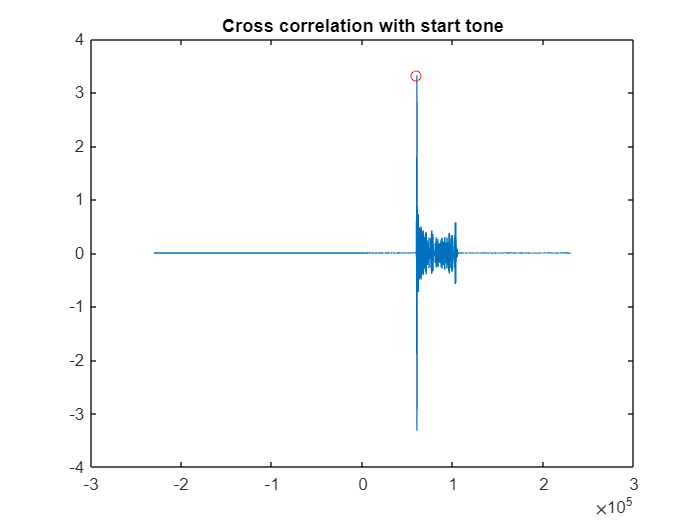

[val, max_idx] = max(abs(r));
start_idx = lags(max_idx);
hold on;
plot(max_idx-N,val, 'ro')
hold off;
title('Cross correlation with start tone')

With the same approach we can analyze the signal to find the stop bit

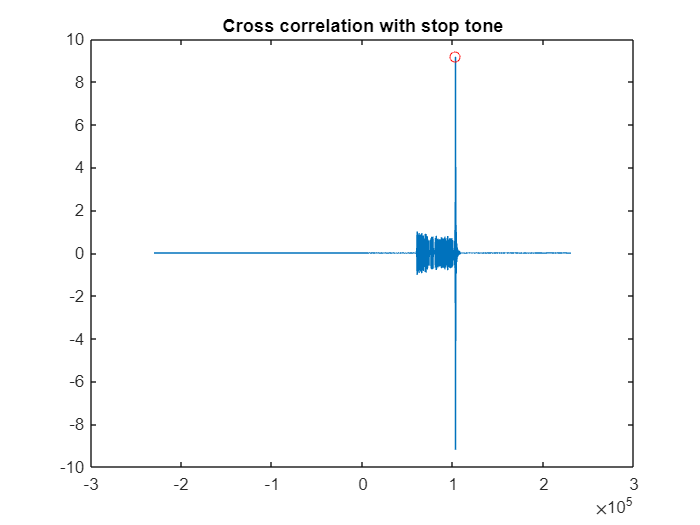

bitstop_tone = sin(2 * pi * FREQ_BIT_STOP * (0:1/Fs:tone_length - 1/Fs));
[r, lags] = xcorr(x, bitstop_tone);
plot(lags,r)
[val, max_idx] = max(abs(r));
stop_idx = lags(max_idx);
hold on;
plot(max_idx-N,val, 'ro')
title('Cross correlation with stop tone')

Finally we can see the rappresentation of all the symbols in the signal

%compute the number of symbols
nseg=round((stop_idx-start_idx)/(tone_length*Fs))+1;
delta=round((stop_idx-start_idx)/nseg)

delta = 435

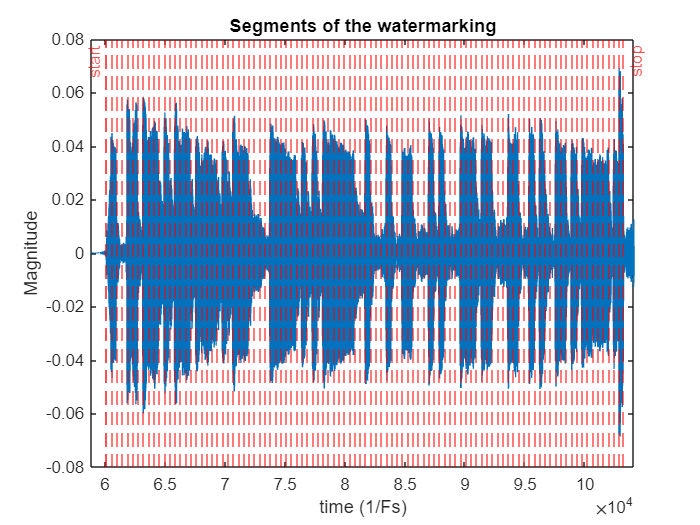

figure
plot(x)
hold on;
xline(start_idx, 'r--', 'LineWidth',  'Label', 'start','LabelHorizontalAlignment','left');
for i=0:nseg-1
    xline(start_idx+i*(tone_length*Fs), 'r--');
end
xline(stop_idx+(tone_length*Fs), 'r--', 'LineWidth',  'Label', 'stop');
xlim([start_idx - 3*tone_length*Fs, stop_idx+3*tone_length*Fs])
hold off;
title('Segments of the watermarking')
xlabel('time (1/Fs)') 
ylabel('Magnitude') 

Search for frequency in a block starting from the previously found index

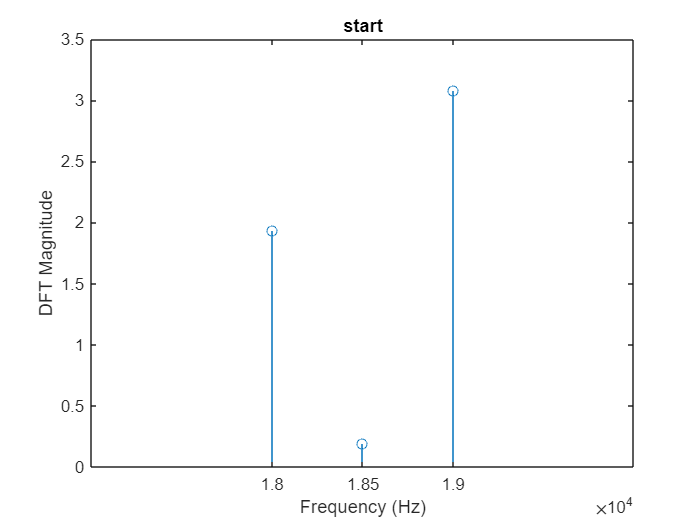

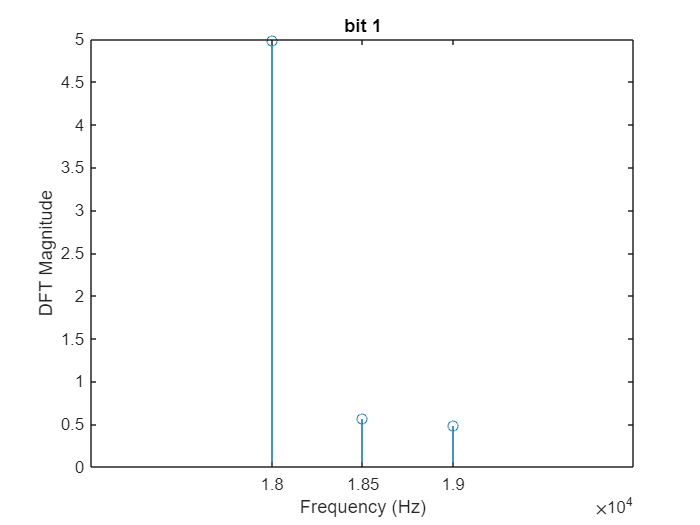

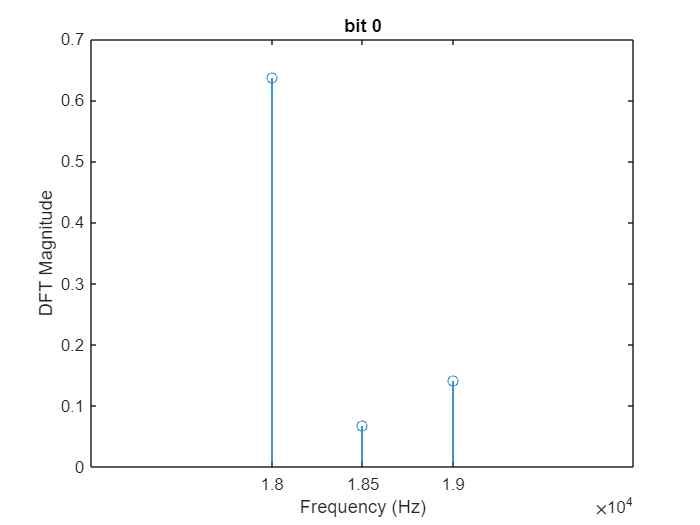

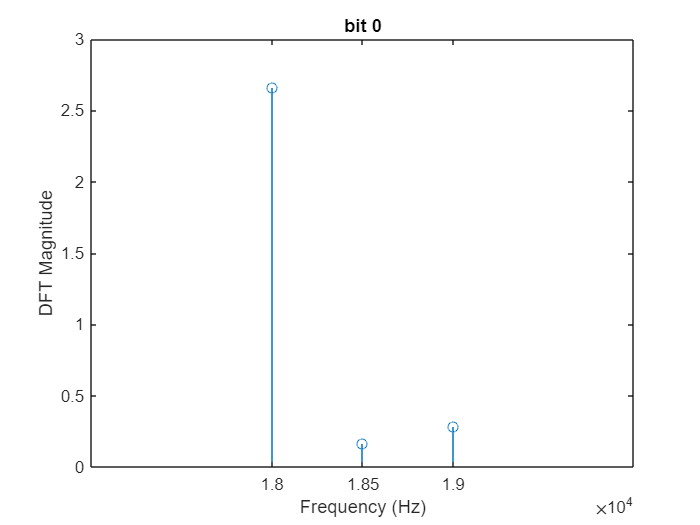

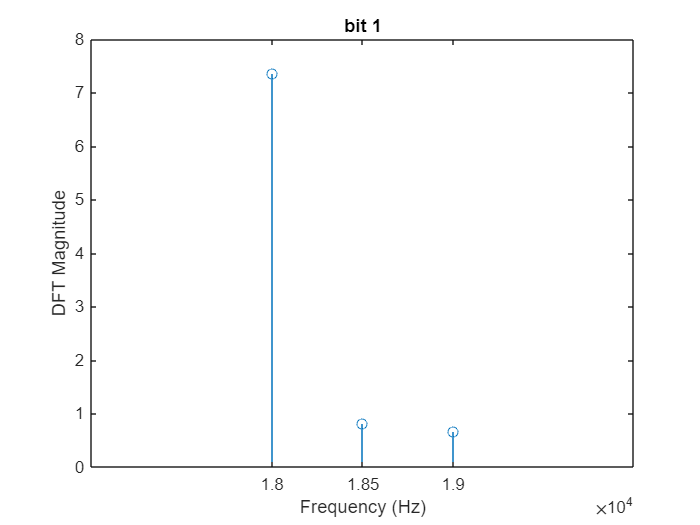

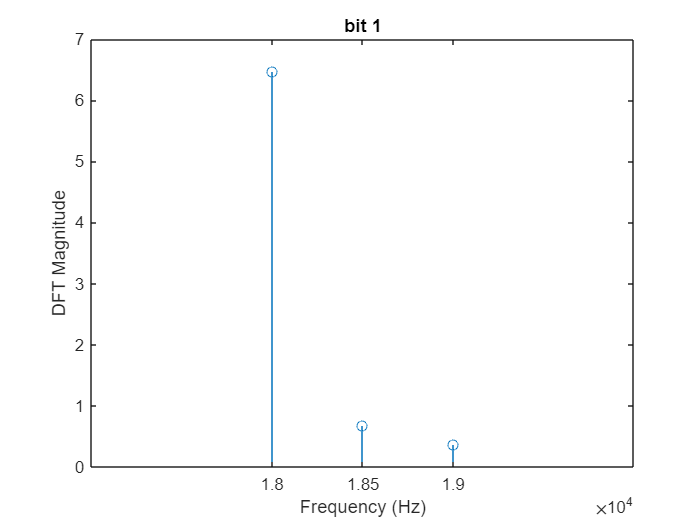

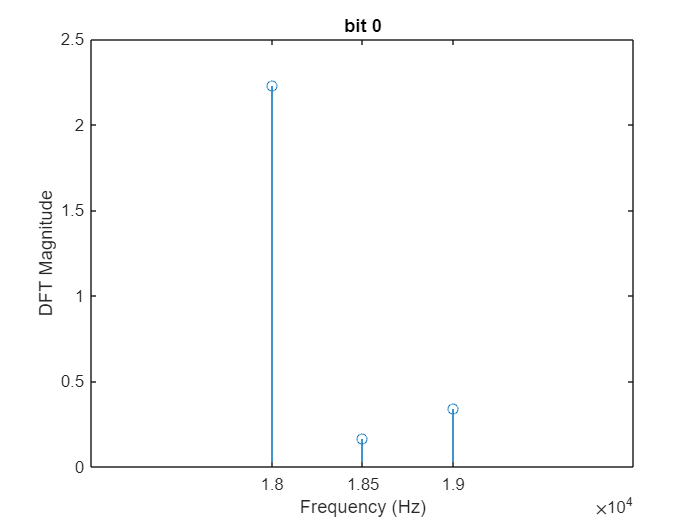

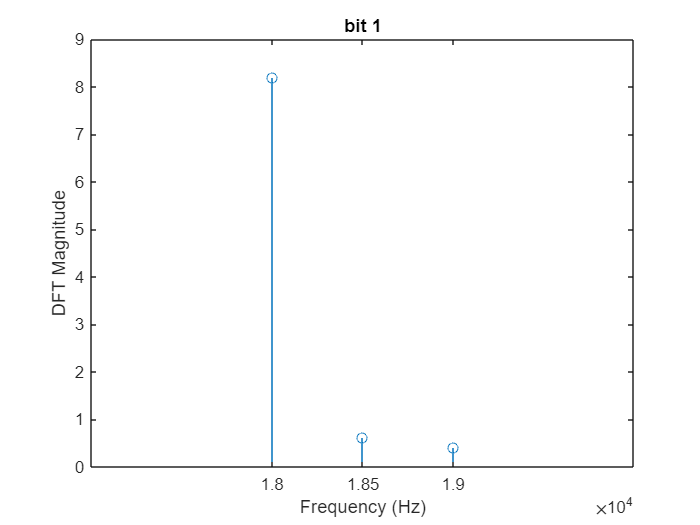

frequencies = [18000, 18500, 19000];
data="";
for i=0:nseg-1
    segment=x(start_idx+i*(tone_length*Fs):start_idx+(i+1)*(tone_length*Fs));
freq_indices = round(frequencies/Fs*length(segment))+1;
dft_data = goertzel(segment,freq_indices);
figure
bit_mag = abs(dft_data); %index 3 is start bit, 2 is stop bit, index 1 is bitdata 

if(bit_mag(3)> thr_start/2 && bit_mag(3) > bit_mag(1))
    label = "start";
    data=data.append('s');
elseif(bit_mag(1)> thr_bit1/(nseg+1)*0.8 && bit_mag(1) > bit_mag(2) && bit_mag(1) > bit_mag(3))
    label = "bit 1";
    data=data.append('1');

elseif(bit_mag(2) > thr_stop/2 && bit_mag(2) > bit_mag(3) && bit_mag(2) > bit_mag(1))
    label = "stop";
    data=data.append('s');
else
    label = "bit 0";
    data=data.append('0');
end

 stem(frequencies,abs(dft_data))
 title(label)
 ax = gca;
 % ylim(ax, [0,50])
 xlim(ax, [17000,20000])
 ax.XTick = frequencies;
 xlabel('Frequency (Hz)')
 ylabel('DFT Magnitude')
end

data

data = "s100110111010111011110101110000111110101011111110100010011000101000111011000110010100110101111101s"

to_process=data.extractAfter('s').extractBefore('s');
to_process=char(to_process)

to_process = '100110111010111011110101110000111110101011111110100010011000101000111011000110010100110101111101'

result="";
for i=0:length(to_process)/8-1
dig=char(bin2dec(to_process(i*8+1:(i+1)*8)));
result=result.append(dig);
end
result

result = "□®õÃêþ□□;□M}"

binary=to_process

binary = '100110111010111011110101110000111110101011111110100010011000101000111011000110010100110101111101'

If the string is encrypted it can be decrypted with the developed tool

S=to_process

S = '100110111010111011110101110000111110101011111110100010011000101000111011000110010100110101111101'

command = ['java -jar decode.jar ' S ' ' key]

command = 'java -jar cyber.jar 100110111010111011110101110000111110101011111110100010011000101000111011000110010100110101111101 AWESOMEKEY'

[status, out] = system(command);
result_decrypted="";
for i=0:length(out)/8-1
dig=char(bin2dec(out(i*8+1:(i+1)*8)));
result_decrypted=result_decrypted.append(dig);
end
result_decrypted

result_decrypted = "B4=O@÷□xciao"

%%if location is sent the string is 
result_decrypted.extractAfter(8)

ans = "ciao"

If the string contains geolocalization data, it can be extracted analyzing the first 8 byte,  since latitude and longiude are sent as float numbers

%%Encrypted version
latitude_e = typecast(uint32(bin2dec(out(1:32))), 'single')

latitude_e = single
45.0599

longitude_e = typecast(uint32(bin2dec(out(33:64))), 'single')

longitude_e = single
7.7215

%%Not encrypted version
latitude = typecast(uint32(bin2dec(binary(1:32))), 'single')

latitude = single
-2.8945e-22

longitude =  typecast(uint32(bin2dec(binary(33:64))), 'single')

longitude = single
-1.5386e+26